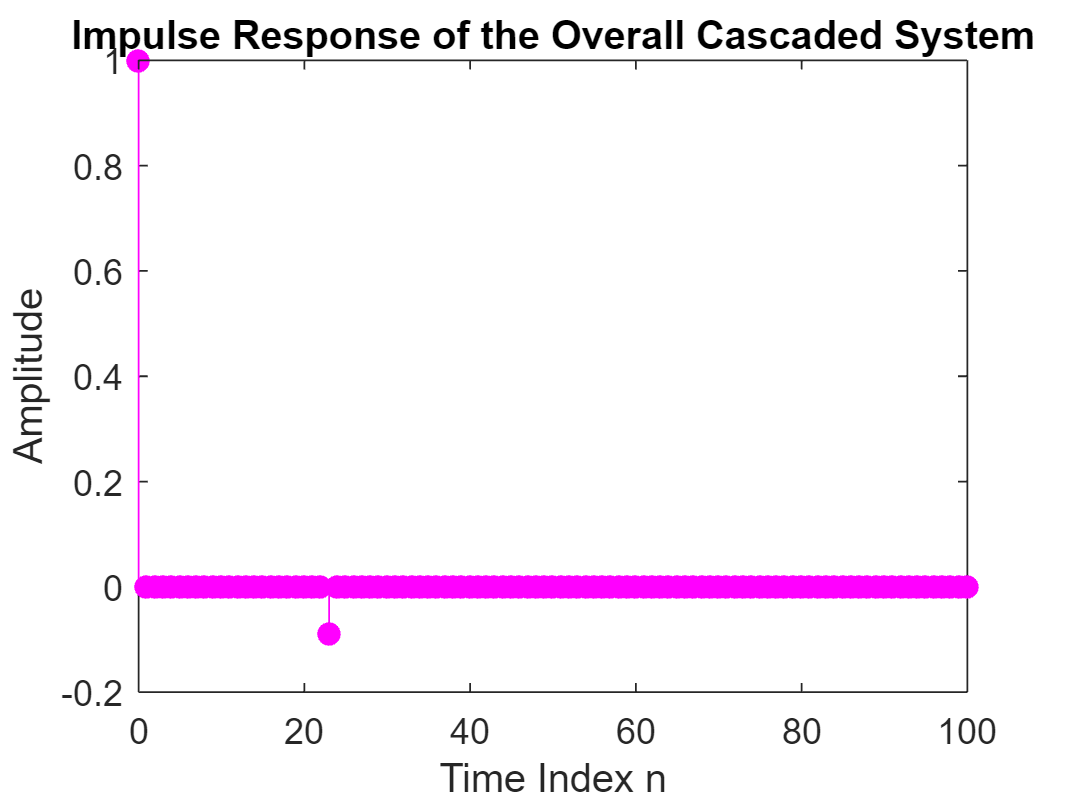

impulse = [1, zeros(1, 100)]; % Length is 101 to ensure sufficient length

% Define the coefficients for FIR FILTER-1
q = 0.9;
b1 = [1, -q];

% Define the coefficients for FIR FILTER-2
r = 0.9;
M = 22;
b2 = r.^(0:M);

% Apply FIR FILTER-1
w = filter(b1, 1, impulse);

% Apply FIR FILTER-2
y = filter(b2, 1, w);

% Plot the impulse response of the overall cascaded system
figure;
stem(0:length(y)-1, y, 'filled', 'm');
title('Impulse Response of the Overall Cascaded System');
xlabel('Time Index n');
ylabel('Amplitude');
xlim([0 100]);